# Create a network with EN functions, eliminitatingd.LibEPANET td.LibEPANEThe need to an EPANET formatted input file

This creates the opportunity to use relational database files or GIS/CAD files. THE USER HAS TO ADD api to call THE EN FUNCTIONS e.g., apiENaddnode.

### Clear - Start Toolkit 

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


#### Initialize epanet class, without inputs.

d = epanet;

EPANET version {20200} loaded (EMT version {v2.2.1}).


### Use gpm for flow units and the Hazen-Williams formula for head loss

d.apiENinit(d.ToolkitConstants.EN_GPM, d.ToolkitConstants.EN_HW, d.LibEPANET, d.ph);

### Add the first junction node to the project with an elevation of 700 ft and a demand of 0

[index, ~]  = d.apiENaddnode('J1', d.ToolkitConstants.EN_JUNCTION, d.LibEPANET, d.ph);
d.apiENsetjuncdata(index, 700, 0, '', d.LibEPANET, d.ph);
d.apiENsetcoord(index, 0, 0, d.LibEPANET, d.ph);

### Add the remaining two junctions with elevations of 710 ft and demands of 250 and 500 gpm, respectively

[index, ~]  = d.apiENaddnode('J2', d.ToolkitConstants.EN_JUNCTION, d.LibEPANET, d.ph);
d.apiENsetjuncdata(index, 710, 250, '', d.LibEPANET, d.ph);
d.apiENsetcoord(index, 0, -100, d.LibEPANET, d.ph);
[index, ~]  = d.apiENaddnode('J3', d.ToolkitConstants.EN_JUNCTION, d.LibEPANET, d.ph);
d.apiENsetjuncdata(index, 710, 500, '', d.LibEPANET, d.ph);
d.apiENsetcoord(index, 100, 0, d.LibEPANET, d.ph);

### Add the reservoir at an elevation of 650 ft

[index, ~]  = d.apiENaddnode('R1', d.ToolkitConstants.EN_RESERVOIR, d.LibEPANET, d.ph);
d.apiENsetnodevalue(index, d.ToolkitConstants.EN_ELEVATION, 650, d.LibEPANET, d.ph);
d.apiENsetcoord(index, -100, 0, d.LibEPANET, d.ph);  

### Add the tank node at elevation of 850 ft, initial water levelat 120 ft, minimum level at 100 ft, maximum level at 150 ft and a diameter of 50.5 ft

[index, ~]  = d.apiENaddnode('T1', d.ToolkitConstants.EN_TANK, d.LibEPANET, d.ph);
d.apiENsettankdata(index, 850, 120, 100, 150, 50.5, 0, '', d.LibEPANET, d.ph);
d.apiENsetcoord(index, 0, 60, d.LibEPANET, d.ph); 

###  Add the pipes to the project, setting their length, diameter, and roughness values

[index, ~] = d.apiENaddlink('P1', d.ToolkitConstants.EN_PIPE, 'J1', 'J2', d.LibEPANET, d.ph);
d.apiENsetpipedata(index, 10560, 12, 100, 0, d.LibEPANET, d.ph);
[index, ~] = d.apiENaddlink('P2', d.ToolkitConstants.EN_PIPE, 'J1', 'T1', d.LibEPANET, d.ph);
d.apiENsetpipedata(index, 5280, 14, 100, 0, d.LibEPANET, d.ph);
[index, ~]= d.apiENaddlink('P3', d.ToolkitConstants.EN_PIPE, 'J1', 'J3', d.LibEPANET, d.ph);
d.apiENsetpipedata(index, 5280, 14, 100, 0, d.LibEPANET, d.ph);
[index, ~] = d.apiENaddlink('P4', d.ToolkitConstants.EN_PIPE, 'J2', 'J3', d.LibEPANET, d.ph);
d.apiENsetpipedata(index, 5280, 14, 100, 0, d.LibEPANET, d.ph); 

###  Add a pump to the project

index = d.apiENaddlink('PUMP', d.ToolkitConstants.EN_PUMP, 'R1', 'J1', d.LibEPANET, d.ph);

###  Create a single point head curve (index = 1) and assign it to the pump

errcode = d.apiENaddcurve('C1', d.LibEPANET, d.ph);
d.apiENsetcurvevalue(1, 1, 1500, 250, d.LibEPANET, d.ph);
d.apiENsetlinkvalue(index, d.ToolkitConstants.EN_PUMP_HCURVE, 1, d.LibEPANET, d.ph);

###  Save the project for future use

d.apiENsaveinpfile('example2.inp', d.LibEPANET, d.ph);

### Plot network

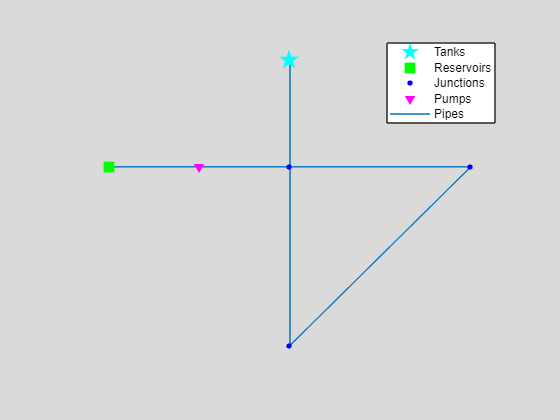

ans =   Axes with properties:

             XLim: [-120 120]
             YLim: [-116 76]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


d.plot

d.apiENclose(d.LibEPANET, d.ph);